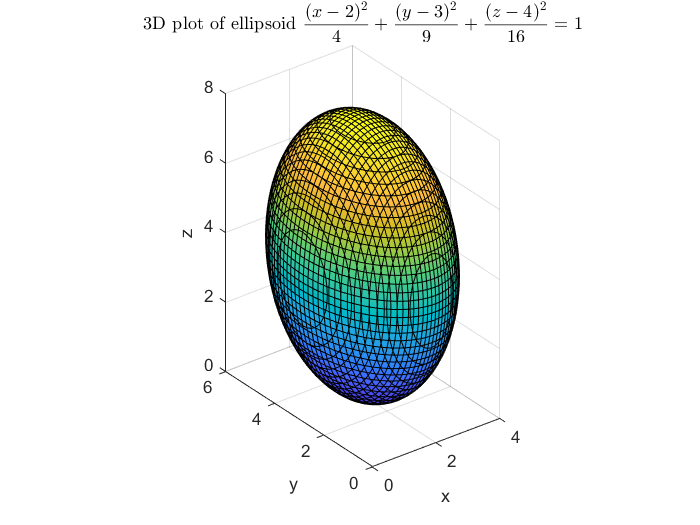

% 第一种方法，利用MATLAB内置的fimplicit函数绘图,解隐函数并绘图
f = @(x,y,z) (x-2).^2/4 + (y-3).^2/9 +(z-4).^2/16-1;
interval=[0 4 0 6 0 8]; %选取合适范围展示整个椭球
fimplicit3(f,interval)
% 坐标轴命名，取标题
xlabel('x')
ylabel('y')
zlabel('z')
title('3D plot of ellipsoid $$\frac{(x-2)^2}{4}+\frac{(y-3)^2}{9}+\frac{(z-4)^2}{16}=1$$','Interpreter','latex')
axis equal

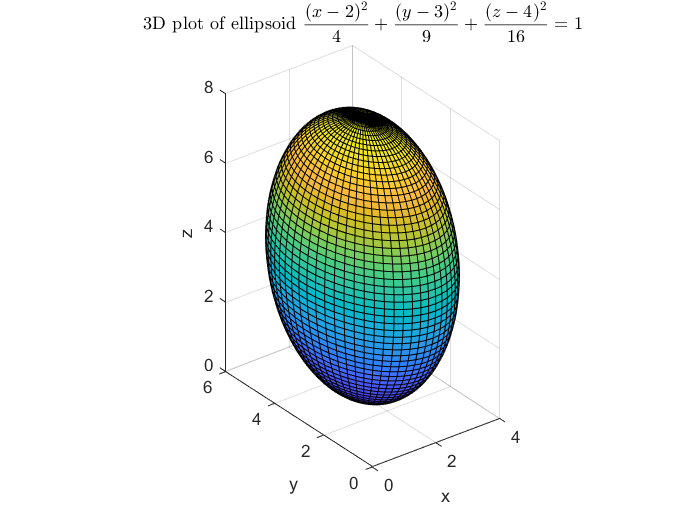


% 第二种方法，利用MATLAB内置的ellipsoid函数绘制，输入中心和三个半周长即可
[x1, y1, z1] = ellipsoid(2,3,4,2,3,4,60);
surf(x1, y1, z1)
% 坐标轴命名，取标题
xlabel('x')
ylabel('y')
zlabel('z')
title('3D plot of ellipsoid $$\frac{(x-2)^2}{4}+\frac{(y-3)^2}{9}+\frac{(z-4)^2}{16}=1$$','Interpreter','latex')
axis equal

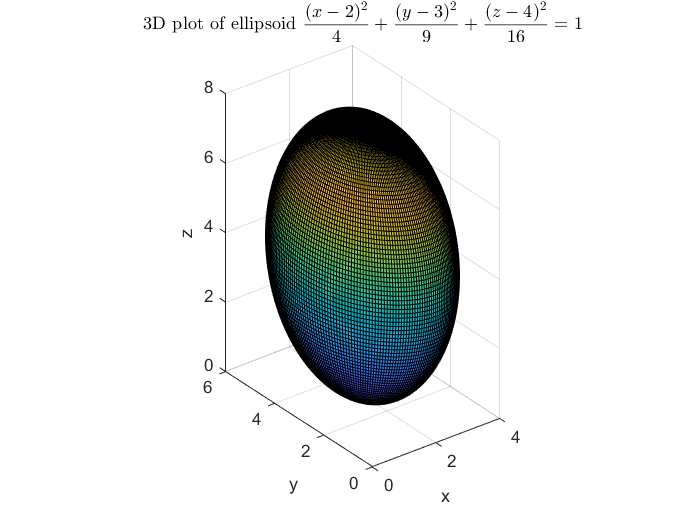


% 第三种方法，利用surf函数和椭球的参数方程自行编程进行绘制
phi=[0:pi/100:pi];
theta=[0:pi/100:2*pi];
[Phi,Theta]=meshgrid(phi,theta);
x2=2*sin(Phi).*cos(Theta)+2;
y2=3*sin(Phi).*sin(Theta)+3;
z2=4*cos(Phi)+4;
surf(x2,y2,z2);
xlim([0 4])
ylim([0 6])
zlim([0 8])
xlabel('x')
ylabel('y')
zlabel('z')
title('3D plot of ellipsoid $$\frac{(x-2)^2}{4}+\frac{(y-3)^2}{9}+\frac{(z-4)^2}{16}=1$$','Interpreter','latex')
axis equal